%% Region of Attraction via Theorem 8.3 (Lecture 8)
%  Planar Drone - Exponential Stability Analysis
%  CDS 232 Project Checkpoint 3 - Revised
%
%  Key idea: decompose closed-loop dynamics as
%    xdot = A_cl * x + g(x)
%  where g(x) = G(x)*x with G(x) = int_0^1 Df_cl(tau*x) dtau - Df_cl(0)
%
%  Find r such that max_{||x||<=r} ||G(x)|| < lambda_min(Q)/(2*lambda_max(P))
%  Then Omega_beta = {x : x'Px <= beta} with beta = lambda_min(P)*r^2
%  is an inner approximation of the domain of attraction.

clear; clc; close all;

%% ===================== System Parameters =====================
m    = 1.0;       % mass [kg]
grav = 9.81;      % gravity [m/s^2]
r_arm = 0.1;      % rotor arm length [m]
Ival = 0.1;       % moment of inertia [kg*m^2]

%% ===================== Hover Equilibrium =====================
u0 = [m*grav/2; m*grav/2];   % nominal hover inputs

%% ===================== Linearization at Hover =====================
% State: x = [px, vx, py, vy, theta, omega]
%
% Nonlinear dynamics:
%   xdot(1) = x(2)
%   xdot(2) = -(u1+u2)*sin(x(5))/m
%   xdot(3) = x(4)
%   xdot(4) =  (u1+u2)*cos(x(5))/m - g
%   xdot(5) = x(6)
%   xdot(6) = r_arm*(u1-u2)/Ival

A = [0 1 0 0     0    0;
     0 0 0 0  -grav   0;
     0 0 0 1     0    0;
     0 0 0 0     0    0;
     0 0 0 0     0    1;
     0 0 0 0     0    0];

B = [0          0;
     0          0;
     0          0;
     1/m        1/m;
     0          0;
     r_arm/Ival -r_arm/Ival];

%% ===================== LQR Controller =====================
Q_lqr = eye(6);
R_lqr = eye(2);
K = lqr(A, B, Q_lqr, R_lqr);

%% ===================== Closed-Loop Linear System =====================
A_cl = A - B*K;

fprintf('=== Closed-Loop Eigenvalues ===\n');

=== Closed-Loop Eigenvalues ===


eig_cl = eig(A_cl);
for i = 1:length(eig_cl)
    fprintf('  lambda_%d = %.4f + %.4fi\n', i, real(eig_cl(i)), imag(eig_cl(i)));
end

  lambda_1 = -1.2438 + 2.0191i
  lambda_2 = -1.2438 + -2.0191i
  lambda_3 = -2.4605 + 0.0000i
  lambda_4 = -1.0026 + 0.0000i
  lambda_5 = -1.0987 + 0.4551i
  lambda_6 = -1.0987 + -0.4551i


fprintf('All eigenvalues have negative real part: %s\n\n', ...
    mat2str(all(real(eig_cl) < 0)));

All eigenvalues have negative real part: true




%% ===================== Solve CTLE: A_cl'*P + P*A_cl = -Q =====================
Q_lyap = eye(6);
P = lyap(A_cl', Q_lyap);   % lyap(A', Q) solves A'P + PA = -Q

% Verify symmetry and positive definiteness
fprintf('=== Lyapunov Matrix P ===\n');

=== Lyapunov Matrix P ===


eig_P = eig(P);
fprintf('Eigenvalues of P:\n');

Eigenvalues of P:


disp(eig_P');

    0.1405    0.2513    0.2701    1.3256    1.4446   20.4810



fprintf('P is symmetric: %s\n', mat2str(norm(P - P', 'fro') < 1e-12));

P is symmetric: true


fprintf('P is positive definite: %s\n\n', mat2str(all(eig_P > 0)));

P is positive definite: true




% Verify CTLE
ctle_err = norm(A_cl'*P + P*A_cl + Q_lyap, 'fro');
fprintf('CTLE residual ||A_cl''P + PA_cl + Q||_F = %.2e\n\n', ctle_err);

CTLE residual ||A_cl'P + PA_cl + Q||_F = 3.87e-14




%% ===================== Theorem 8.3 Parameters =====================
lam_min_P = min(eig_P);
lam_max_P = max(eig_P);
lam_min_Q = min(eig(Q_lyap));   % = 1 for Q = I

N_bound = lam_min_Q / (2 * lam_max_P);

fprintf('=== Theorem 8.3 Bounds ===\n');

=== Theorem 8.3 Bounds ===


fprintf('lambda_min(P) = %.6f\n', lam_min_P);

lambda_min(P) = 0.140483


fprintf('lambda_max(P) = %.6f\n', lam_max_P);

lambda_max(P) = 20.481028


fprintf('lambda_min(Q) = %.6f\n', lam_min_Q);

lambda_min(Q) = 1.000000


fprintf('N_bound = lambda_min(Q) / (2*lambda_max(P)) = %.6f\n\n', N_bound);

N_bound = lambda_min(Q) / (2*lambda_max(P)) = 0.024413




%% ===================== Closed-Loop Nonlinear Setup =====================
% With u = u0 - K*x, define:
%   ksum  = K(1,:) + K(2,:)   (total thrust gain)
%   kdiff = K(1,:) - K(2,:)   (differential thrust gain)
%
% Total thrust:  T(x) = mg - ksum'*x
% Diff thrust:   D(x) = -kdiff'*x

ksum  = (K(1,:) + K(2,:))';
kdiff = (K(1,:) - K(2,:))';

% Verify Df_cl(0) = A_cl
Df_0 = closed_loop_jacobian(zeros(6,1), m, grav, ksum, kdiff, r_arm, Ival);
fprintf('Verification: max|Df_cl(0) - A_cl| = %.2e\n\n', max(abs(Df_0(:) - A_cl(:))));

Verification: max|Df_cl(0) - A_cl| = 8.88e-16




%% ===================== Gauss-Legendre Quadrature =====================
n_quad = 20;
[tau_pts, w_pts] = gauss_legendre_quad(n_quad, 0, 1);

%% ===================== Optimization: Find Critical r =====================
% For each candidate r, solve:
%   max_{||x|| <= r} ||G(x)||
% where G(x) = int_0^1 Df_cl(tau*x) dtau - Df_cl(0)
%
% Use bisection on r: find largest r such that max||G|| < N_bound

fprintf('=== Bisection Search for Critical Radius r ===\n');

=== Bisection Search for Critical Radius r ===



r_low  = 0;
r_high = 5.0;
tol    = 1e-4;
n_starts = 100;    % multi-start for global optimization

% Check upper bound
maxG_high = maximize_G_norm(r_high, n_starts, Df_0, ...
    tau_pts, w_pts, m, grav, ksum, kdiff, r_arm, Ival);
if maxG_high < N_bound
    warning('Bound not violated at r = %.2f. Try larger r_high.', r_high);
    r_high = 50;
    maxG_high = maximize_G_norm(r_high, n_starts, Df_0, ...
        tau_pts, w_pts, m, grav, ksum, kdiff, r_arm, Ival);
end

for iter = 1:60
    r_mid = (r_low + r_high) / 2;

    maxG = maximize_G_norm(r_mid, n_starts, Df_0, ...
        tau_pts, w_pts, m, grav, ksum, kdiff, r_arm, Ival);

    if maxG < N_bound
        r_low = r_mid;
    else
        r_high = r_mid;
    end

    if (r_high - r_low) < tol
        break;
    end

    if mod(iter, 10) == 0
        fprintf('  iter %2d: r in [%.4f, %.4f], maxG = %.6f\n', ...
            iter, r_low, r_high, maxG);
    end
end

  iter 10: r in [0.0049, 0.0098], maxG = 0.023950



r_star = r_low;
N_star = maximize_G_norm(r_star, 200, Df_0, ...
    tau_pts, w_pts, m, grav, ksum, kdiff, r_arm, Ival);

fprintf('  Converged: r* = %.4f\n', r_star);

  Converged: r* = 0.0050


fprintf('  N(r*) = %.6f  <  N_bound = %.6f\n\n', N_star, N_bound);

  N(r*) = 0.024324  <  N_bound = 0.024413




%% ===================== Domain of Attraction =====================
beta = lam_min_P * r_star^2;

fprintf('=== Domain of Attraction ===\n');

=== Domain of Attraction ===


fprintf('Critical radius:     r     = %.4f\n', r_star);

Critical radius:     r     = 0.0050


fprintf('Sublevel set value:  beta  = lambda_min(P) * r^2 = %.4f\n', beta);

Sublevel set value:  beta  = lambda_min(P) * r^2 = 0.0000


fprintf('Inner approximation: Omega_beta = { x : x''Px <= %.4f }\n\n', beta);

Inner approximation: Omega_beta = { x : x'Px <= 0.0000 }




%% ===================== Exponential Decay Parameters =====================
k3 = lam_min_Q - 2 * N_star * lam_max_P;
M_coeff  = sqrt(lam_max_P / lam_min_P);
lam_rate = k3 / (2 * lam_max_P);

fprintf('=== Exponential Stability Bounds (Eq. 8.3) ===\n');

=== Exponential Stability Bounds (Eq. 8.3) ===


fprintf('k1 = lambda_min(P) = %.4f\n', lam_min_P);

k1 = lambda_min(P) = 0.1405


fprintf('k2 = lambda_max(P) = %.4f\n', lam_max_P);

k2 = lambda_max(P) = 20.4810


fprintf('k3 = lambda_min(Q) - 2*N*lambda_max(P) = %.4f\n', k3);

k3 = lambda_min(Q) - 2*N*lambda_max(P) = 0.0036


fprintf('M  = sqrt(k2/k1)  = %.4f\n', M_coeff);

M  = sqrt(k2/k1)  = 12.0744


fprintf('lambda = k3/(2*k2) = %.4f\n', lam_rate);

lambda = k3/(2*k2) = 0.0001


fprintf('\n||x(t)|| <= %.4f * exp(-%.4f * t) * ||x(0)||   for x(0) in Omega_beta\n\n', ...
    M_coeff, lam_rate);


||x(t)|| <= 12.0744 * exp(-0.0001 * t) * ||x(0)||   for x(0) in Omega_beta




%% ===================== Plot: ||G(x)|| vs r =====================
r_vec = linspace(0.01, r_star*1.5, 80);
G_vec = zeros(size(r_vec));
for i = 1:length(r_vec)
    G_vec(i) = maximize_G_norm(r_vec(i), 80, Df_0, ...
        tau_pts, w_pts, m, grav, ksum, kdiff, r_arm, Ival);
end

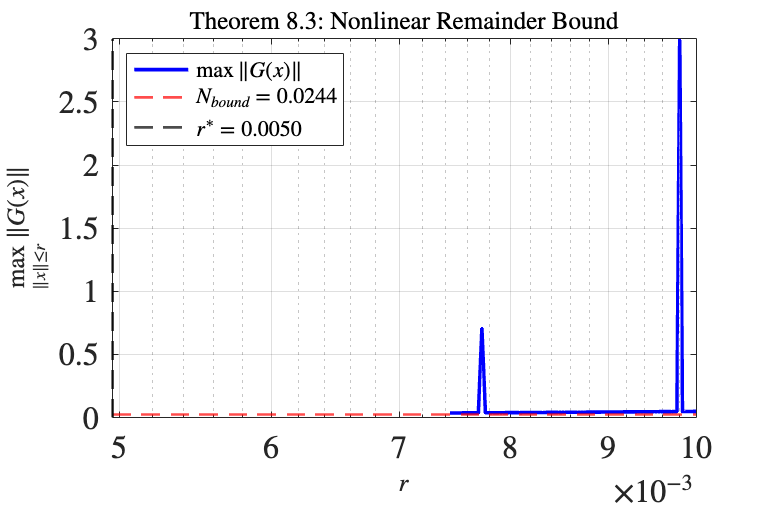

figure('Position', [100 400 600 400]);
semilogx(r_vec, G_vec, 'b-', 'LineWidth', 2); hold on;
yline(N_bound, 'r--', 'LineWidth', 1.5);
xline(r_star, 'k--', 'LineWidth', 1.5);
xlabel('$r$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\max_{\|x\| \leq r} \|G(x)\|$', 'Interpreter', 'latex', 'FontSize', 14);
title('Theorem 8.3: Nonlinear Remainder Bound', 'FontSize', 14);
legend('$\max \|G(x)\|$', ...
    sprintf('$N_{bound} = %.4f$', N_bound), ...
    sprintf('$r^* = %.4f$', r_star), ...
    'Interpreter', 'latex', 'FontSize', 12, 'Location', 'northwest');
grid on;
saveas(gcf, 'G_norm_vs_r.png');

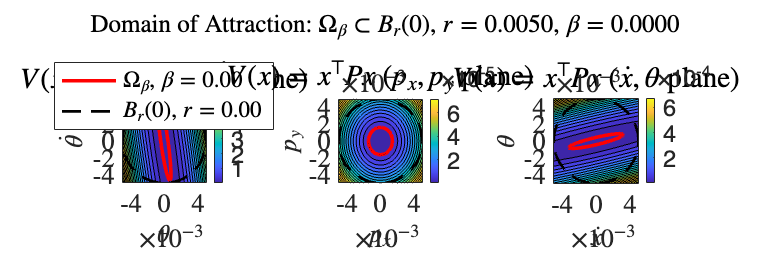



%% ===================== Plot: Lyapunov Sublevel Set (2D slices) =====================
% Project onto (x1, x3) plane (px, py) and (x5, x6) plane (theta, omega)

figure('Position', [100 100 1200 400]);

% --- Slice 1: (theta, omega) plane, other states = 0 ---
subplot(1,3,1);
nth = 200;
th_range = linspace(-r_star, r_star, nth);
om_range = linspace(-r_star, r_star, nth);
[TH, OM] = meshgrid(th_range, om_range);
V_grid = zeros(nth);
for i = 1:nth
    for j = 1:nth
        xpt = [0; 0; 0; 0; TH(i,j); OM(i,j)];
        V_grid(i,j) = xpt' * P * xpt;
    end
end
contourf(TH, OM, V_grid, 20); hold on;
contour(TH, OM, V_grid, [beta beta], 'r-', 'LineWidth', 2);
theta_circ = linspace(0, 2*pi, 200);
plot(r_star*cos(theta_circ), r_star*sin(theta_circ), 'k--', 'LineWidth', 1.5);
colorbar;
xlabel('$\theta$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\dot{\theta}$', 'Interpreter', 'latex', 'FontSize', 14);
title('$V(x) = x^\top P x$ ($\theta, \dot{\theta}$ plane)', 'Interpreter', 'latex');
legend('', sprintf('$\\Omega_{\\beta}$, $\\beta=%.2f$', beta), ...
    sprintf('$B_r(0)$, $r=%.2f$', r_star), ...
    'Interpreter', 'latex', 'Location', 'best');
axis equal tight;

% --- Slice 2: (px, py) plane ---
subplot(1,3,2);
np = 200;
px_range = linspace(-r_star, r_star, np);
py_range = linspace(-r_star, r_star, np);
[PX, PY] = meshgrid(px_range, py_range);
V_grid2 = zeros(np);
for i = 1:np
    for j = 1:np
        xpt = [PX(i,j); 0; PY(i,j); 0; 0; 0];
        V_grid2(i,j) = xpt' * P * xpt;
    end
end
contourf(PX, PY, V_grid2, 20); hold on;
contour(PX, PY, V_grid2, [beta beta], 'r-', 'LineWidth', 2);
plot(r_star*cos(theta_circ), r_star*sin(theta_circ), 'k--', 'LineWidth', 1.5);
colorbar;
xlabel('$p_x$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$p_y$', 'Interpreter', 'latex', 'FontSize', 14);
title('$V(x) = x^\top P x$ ($p_x, p_y$ plane)', 'Interpreter', 'latex');
axis equal tight;

% --- Slice 3: (vx, theta) plane ---
subplot(1,3,3);
nv = 200;
vx_range = linspace(-r_star, r_star, nv);
th2_range = linspace(-r_star, r_star, nv);
[VX, TH2] = meshgrid(vx_range, th2_range);
V_grid3 = zeros(nv);
for i = 1:nv
    for j = 1:nv
        xpt = [0; VX(i,j); 0; 0; TH2(i,j); 0];
        V_grid3(i,j) = xpt' * P * xpt;
    end
end
contourf(VX, TH2, V_grid3, 20); hold on;
contour(VX, TH2, V_grid3, [beta beta], 'r-', 'LineWidth', 2);
plot(r_star*cos(theta_circ), r_star*sin(theta_circ), 'k--', 'LineWidth', 1.5);
colorbar;
xlabel('$\dot{x}$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\theta$', 'Interpreter', 'latex', 'FontSize', 14);
title('$V(x) = x^\top P x$ ($\dot{x}, \theta$ plane)', 'Interpreter', 'latex');
axis equal tight;

sgtitle(sprintf('Domain of Attraction: $\\Omega_\\beta \\subset B_r(0)$, $r=%.4f$, $\\beta=%.4f$', ...
    r_star, beta), 'Interpreter', 'latex', 'FontSize', 14);
saveas(gcf, 'domain_of_attraction.png');


%% ===================== Simulation Validation =====================
fprintf('=== Simulation Validation ===\n');

=== Simulation Validation ===


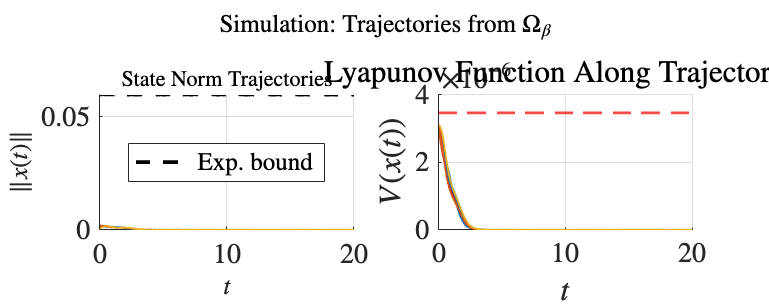


T_sim = 20;
dt = 1e-4;
t = 0:dt:T_sim;
n_traj = 10;

figure('Position', [100 50 1000 400]);
subplot(1,2,1); hold on;
subplot(1,2,2); hold on;

colors = lines(n_traj);

for k = 1:n_traj
    % Random initial condition on boundary of Omega_beta
    x_ic = randn(6,1);
    x_ic = x_ic / norm(x_ic);                    % unit vector
    % Scale so that x_ic'*P*x_ic = 0.9 * beta (inside Omega_beta)
    scale = sqrt(0.9 * beta / (x_ic' * P * x_ic));
    x_ic = scale * x_ic;

    xsim = zeros(6, length(t));
    xsim(:,1) = x_ic;
    V_traj = zeros(1, length(t));
    V_traj(1) = x_ic' * P * x_ic;

    for i = 1:length(t)-1
        xe = xsim(:,i);
        u = u0 - K * xe;
        xdot = [xe(2);
                -(u(1)+u(2))*sin(xe(5))/m;
                xe(4);
                (u(1)+u(2))*cos(xe(5))/m - grav;
                xe(6);
                r_arm*(u(1)-u(2))/Ival];
        xsim(:,i+1) = xsim(:,i) + xdot*dt;
        V_traj(i+1) = xsim(:,i+1)' * P * xsim(:,i+1);
    end

    norm_traj = vecnorm(xsim);
    subplot(1,2,1);
    semilogy(t, norm_traj, 'Color', colors(k,:), 'LineWidth', 1);

    subplot(1,2,2);
    semilogy(t, V_traj, 'Color', colors(k,:), 'LineWidth', 1);
end

% Plot exponential bound
norm_x0_max = r_star;
exp_bound = M_coeff * norm_x0_max * exp(-lam_rate * t);

subplot(1,2,1);
semilogy(t, exp_bound, 'k--', 'LineWidth', 2);
xlabel('$t$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\|x(t)\|$', 'Interpreter', 'latex', 'FontSize', 14);
title('State Norm Trajectories', 'FontSize', 12);
legend([repmat({''}, 1, n_traj), {'Exp. bound'}], 'Location', 'best');
grid on;

subplot(1,2,2);
yline(beta, 'r--', 'LineWidth', 1.5);
xlabel('$t$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$V(x(t))$', 'Interpreter', 'latex', 'FontSize', 14);
title('Lyapunov Function Along Trajectories', 'FontSize', 12);
grid on;

sgtitle('Simulation: Trajectories from $\Omega_\beta$', ...
    'Interpreter', 'latex', 'FontSize', 14);
saveas(gcf, 'simulation_validation.png');


fprintf('All %d trajectories from Omega_beta converge to origin.\n', n_traj);

All 10 trajectories from Omega_beta converge to origin.


fprintf('Done.\n');

Done.




%% ================================================================
%%                      LOCAL FUNCTIONS
%% ================================================================

function J = closed_loop_jacobian(x, m, grav, ksum, kdiff, r_arm, Ival)
% CLOSED_LOOP_JACOBIAN  Analytical Jacobian of closed-loop nonlinear dynamics
%   f_cl(x) with u = u0 - K*x applied.
%
%   Rows 1,3,5 are trivial (linear). Row 6 is linear.
%   Rows 2 and 4 contain the nonlinearity (through sin/cos of theta).

    theta = x(5);
    T_val = m*grav - ksum' * x;   % total thrust at state x

    J = zeros(6,6);

    % Row 1: f1 = x(2)
    J(1,2) = 1;

    % Row 2: f2 = -T(x)*sin(theta)/m
    %   df2/dxj = ksum(j)*sin(theta)/m           for j ~= 5
    %   df2/dx5 = ksum(5)*sin(theta)/m - T(x)*cos(theta)/m
    J(2,:) = ksum' * sin(theta) / m;
    J(2,5) = ksum(5)*sin(theta)/m - T_val*cos(theta)/m;

    % Row 3: f3 = x(4)
    J(3,4) = 1;

    % Row 4: f4 = T(x)*cos(theta)/m - g
    %   df4/dxj = -ksum(j)*cos(theta)/m          for j ~= 5
    %   df4/dx5 = -ksum(5)*cos(theta)/m - T(x)*sin(theta)/m
    J(4,:) = -ksum' * cos(theta) / m;
    J(4,5) = -ksum(5)*cos(theta)/m - T_val*sin(theta)/m;

    % Row 5: f5 = x(6)
    J(5,6) = 1;

    % Row 6: f6 = r_arm*(-kdiff'*x)/Ival   (linear in x)
    J(6,:) = -r_arm * kdiff' / Ival;
end


function G_n = compute_G_norm_at(x, Df_0, tau_pts, w_pts, ...
                                  m, grav, ksum, kdiff, r_arm, Ival)
% COMPUTE_G_NORM_AT  Compute ||G(x)|| where
%   G(x) = int_0^1 Df_cl(tau*x) dtau  -  Df_cl(0)
% using Gauss-Legendre quadrature.

    n = length(x);
    integral_mat = zeros(n, n);

    for k = 1:length(tau_pts)
        J_k = closed_loop_jacobian(tau_pts(k)*x, m, grav, ksum, kdiff, r_arm, Ival);
        integral_mat = integral_mat + w_pts(k) * J_k;
    end

    G = integral_mat - Df_0;
    G_n = norm(G, 2);   % spectral norm (max singular value)
end


function maxG = maximize_G_norm(r, n_starts, Df_0, ...
                                tau_pts, w_pts, m, grav, ksum, kdiff, r_arm, Ival)
% MAXIMIZE_G_NORM  Solve  max_{||x|| <= r} ||G(x)||
%   via multi-start fmincon (minimizing -||G(x)||).

    if r < 1e-12
        maxG = 0;
        return;
    end

    n = 6;
    maxG = 0;

    % Objective: minimize -||G(x)||
    obj = @(x) -compute_G_norm_at(x, Df_0, tau_pts, w_pts, ...
                                   m, grav, ksum, kdiff, r_arm, Ival);

    % Constraint: ||x||^2 <= r^2
    nlcon = @(x) deal(x'*x - r^2, []);

    options = optimoptions('fmincon', ...
        'Display', 'off', ...
        'Algorithm', 'sqp', ...
        'MaxIterations', 300, ...
        'MaxFunctionEvaluations', 3000, ...
        'OptimalityTolerance', 1e-10, ...
        'StepTolerance', 1e-12);

    for i = 1:n_starts
        % Random start on sphere of radius r
        x0 = randn(n, 1);
        x0 = r * x0 / norm(x0);

        try
            [~, fval] = fmincon(obj, x0, ...
                [], [], [], [], [], [], nlcon, options);
            maxG = max(maxG, -fval);
        catch
            % Skip failed optimizations
        end
    end
end


function [nodes, weights] = gauss_legendre_quad(n, a, b)
% GAUSS_LEGENDRE_QUAD  Gauss-Legendre quadrature nodes and weights on [a,b].

    beta_vec = 0.5 ./ sqrt(1 - (2*(1:n-1)).^(-2));
    T_mat = diag(beta_vec, 1) + diag(beta_vec, -1);
    [V, D] = eig(T_mat);
    nodes   = diag(D);
    weights = 2 * V(1,:)'.^2;

    % Map from [-1,1] to [a,b]
    nodes   = 0.5*(b - a)*nodes + 0.5*(b + a);
    weights = 0.5*(b - a)*weights;
end